# Segmentació 2

## Millora exercici segmentar

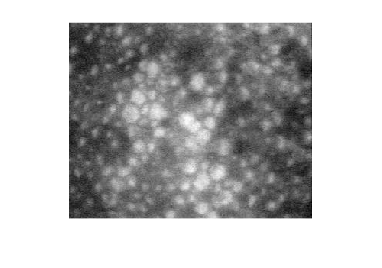

I = imread('cornea.tif');
imshow(I);

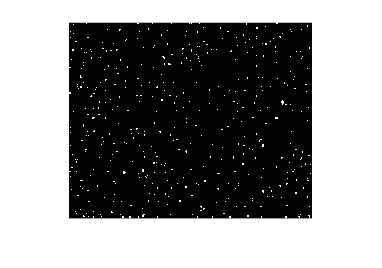

% Màxims regionals
I = medfilt2(I, [4, 4]);
MARK_C = imregionalmax(I);
imshow(MARK_C);

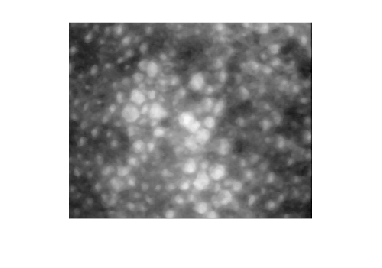

% imatge reconstruccio
IREC = imreconstruct(I.*uint8(MARK_C),I);
imshow(IREC);

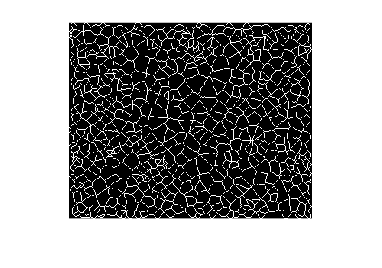

% SKIZ
SK = bwskel(not(MARK_C));
MARK_B = bwmorph(SK,'spur',Inf);
MARK_B = MARK_B & not(bwhitmiss(MARK_B,[-1,-1,-1;-1,1,-1;-1,-1,-1]));
imshow(MARK_B);

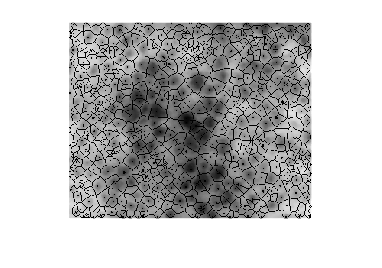

% Imatge de marques
MARKERS = (255-I) .* uint8(not(MARK_B)) .* uint8(not(MARK_C));
imshow(MARKERS);

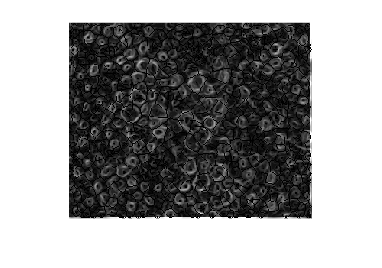

% Imatge gradient, eliminar mínims locals
G = uint8(imgradient(IREC));
N = imimposemin(G, MARK_B|MARK_C);
imshow(N,[]);

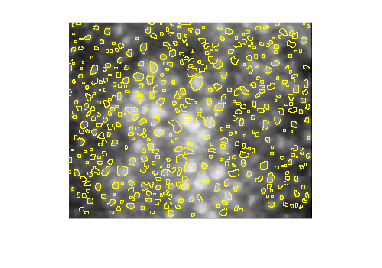

% watershed
WS = watershed(N);
IB = WS == 0;
RGB = imoverlay(I, IB);
imshow(RGB);

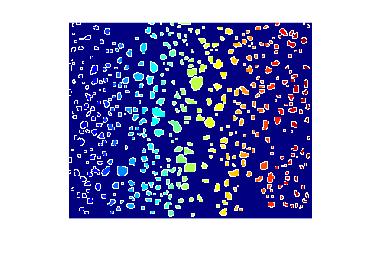

imshow(label2rgb(WS));

## Segmentació assistida

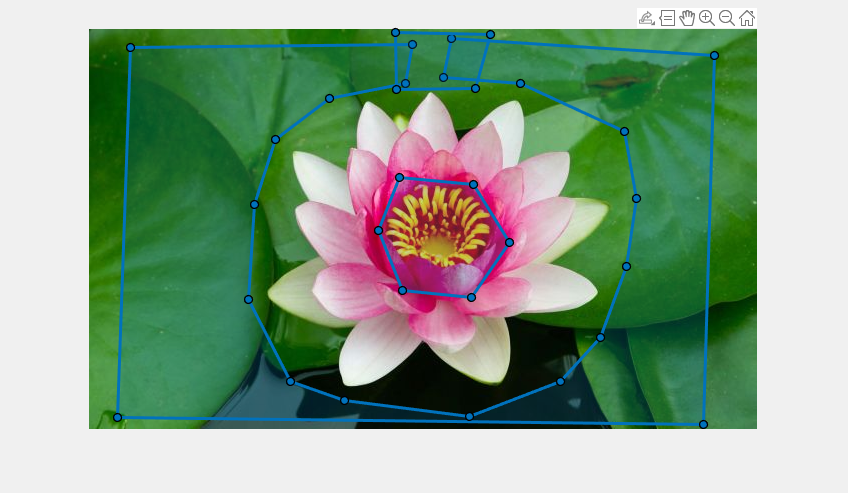

I = imread("nenufar.jpg");
gray = rgb2gray(I);
imshow(I);
roiPoints = drawpolygon;
d1 = poly2mask(roiPoints.Position(:,1),roiPoints.Position(:,2), size(I,1), size(I,2));
roiPoints = drawpolygon;
d2 = poly2mask(roiPoints.Position(:,1),roiPoints.Position(:,2), size(I,1), size(I,2));
roiPoints = drawpolygon;

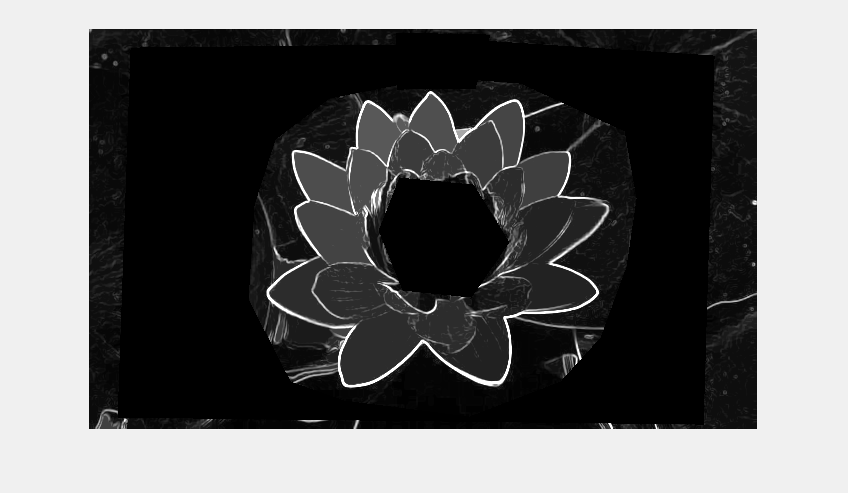

d3 = poly2mask(roiPoints.Position(:,1),roiPoints.Position(:,2), size(I,1), size(I,2));

MASK = d1|d2|d3;

G = uint8(imgradient(gray));
N = imimposemin(G, MASK);
imshow(N,[]);

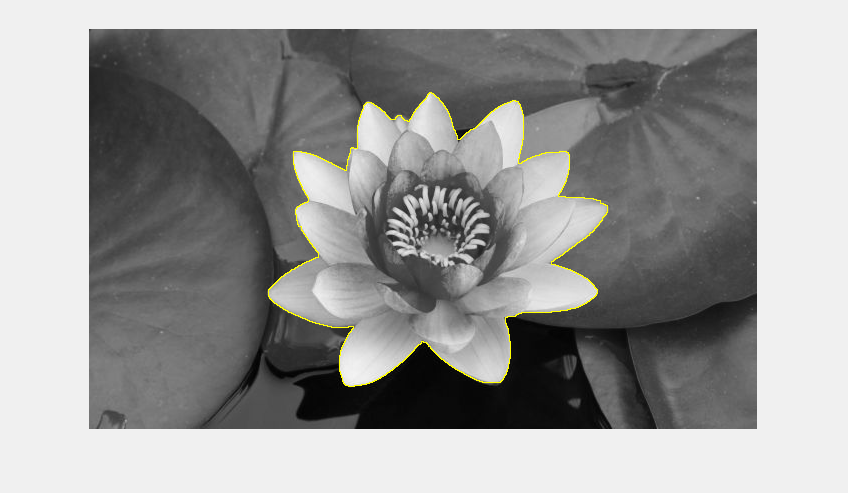


WS = watershed(N);
IB = WS == 0;
RGB = imoverlay(gray, IB);
imshow(RGB);

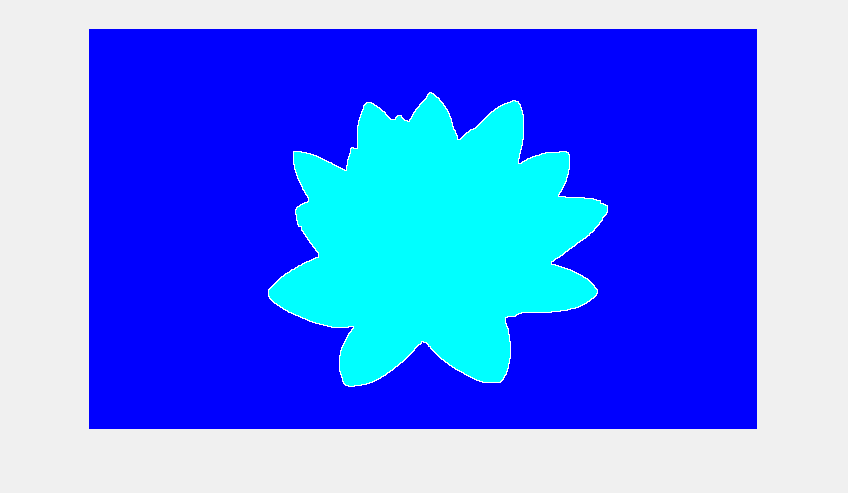

imshow(label2rgb(WS));

## Segmentació per K-Means

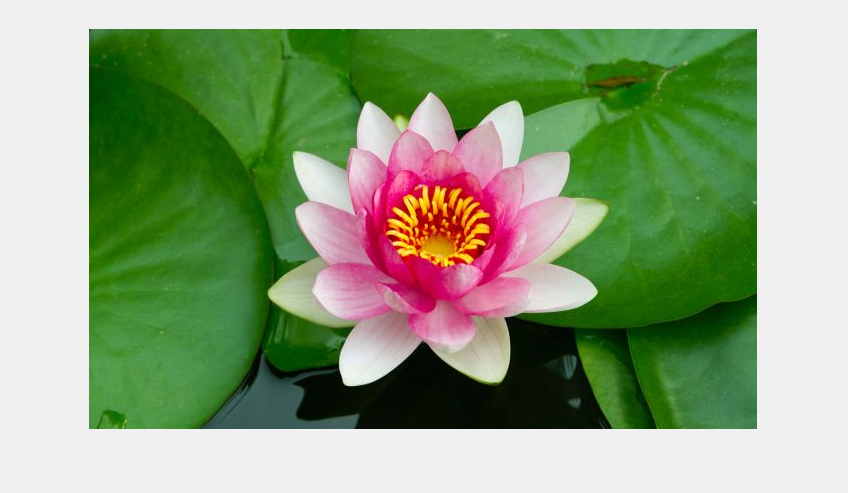

% reduir el nombre de colors d'una imatge
I = imread("nenufar.jpg");
imshow(I);

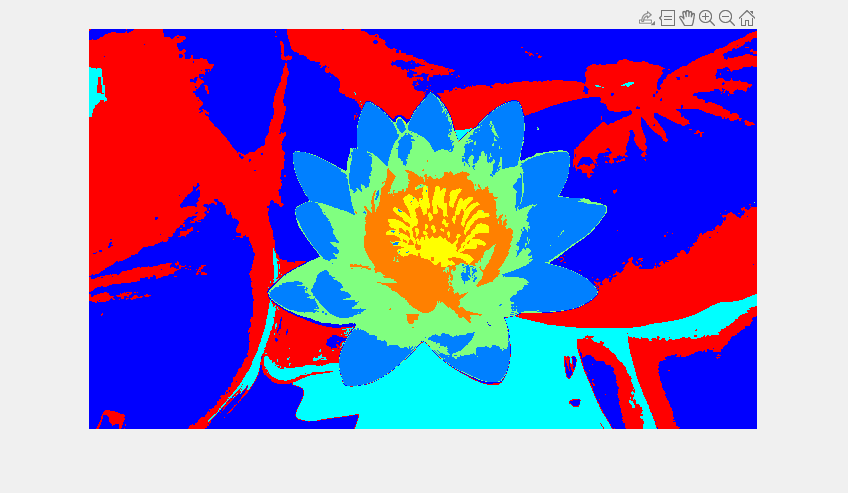

R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);
O = [R(:),G(:),B(:)];
[C Cen] = kmeans(double(O), 7);
[f c p] = size(I);
C = reshape(C,[f c]);
imshow(label2rgb(C));

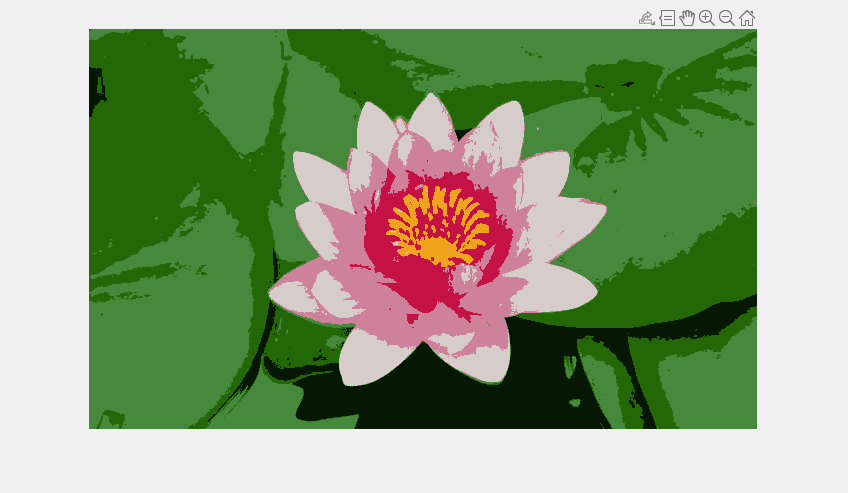


RGB2 = uint8(zeros(f,c,p));

for i = 1 : f
    for j = 1 : c
        RGB2(i,j,1) = uint8(Cen(C(i,j),1));
        RGB2(i,j,2) = uint8(Cen(C(i,j),2));
        RGB2(i,j,3) = uint8(Cen(C(i,j),3));
    end
end
imshow(RGB2);

## Segmentació per Graph cut

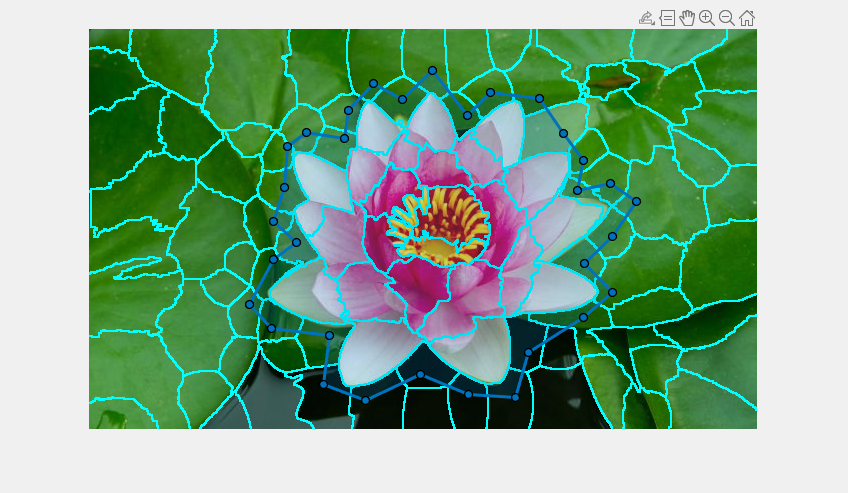

I = imread("nenufar.jpg");
[SP,N] = superpixels(I,100);
BW = boundarymask(SP);
imshow(imoverlay(I,BW,'cyan'));
roiPoints = drawpolygon;

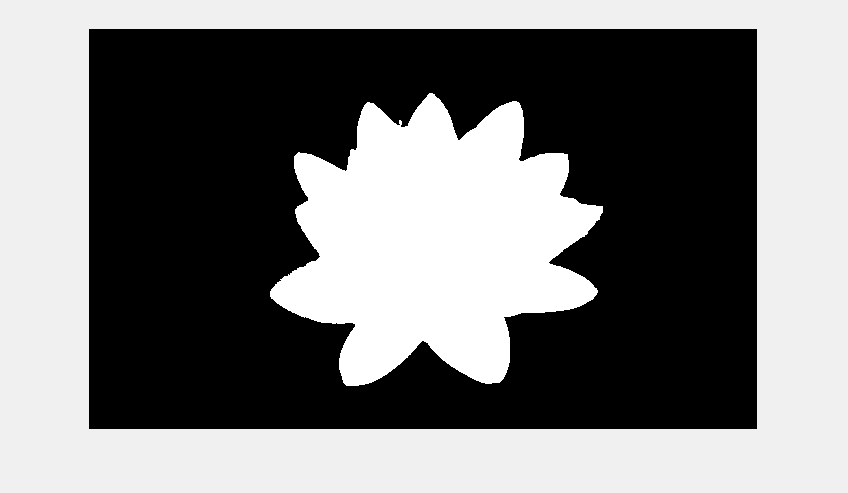

roi = poly2mask(roiPoints.Position(:,1),roiPoints.Position(:,2), size(I,1), size(I,2));
BW = grabcut(I,SP,roi);
imshow(BW);

## Exercici segmentació amb rectangle

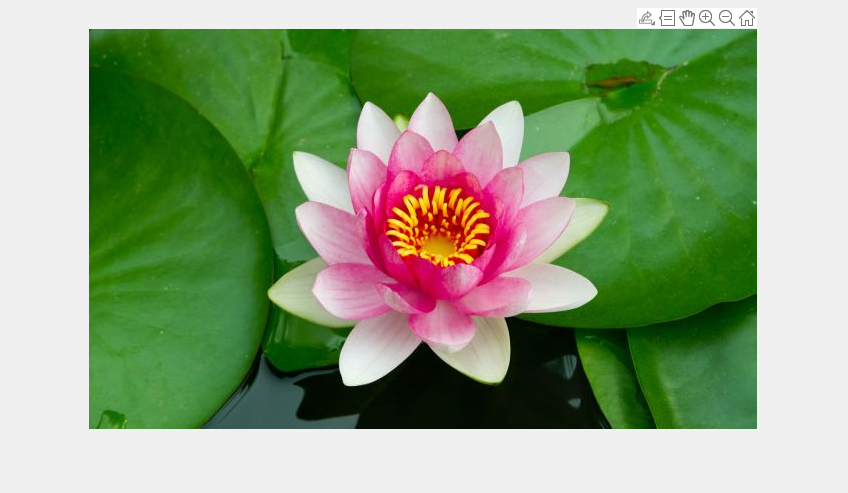

% reduir el nombre de colors d'una imatge
n_colors = 7;

I = imread("nenufar.jpg");
imshow(I);
rect = uint8(getrect);

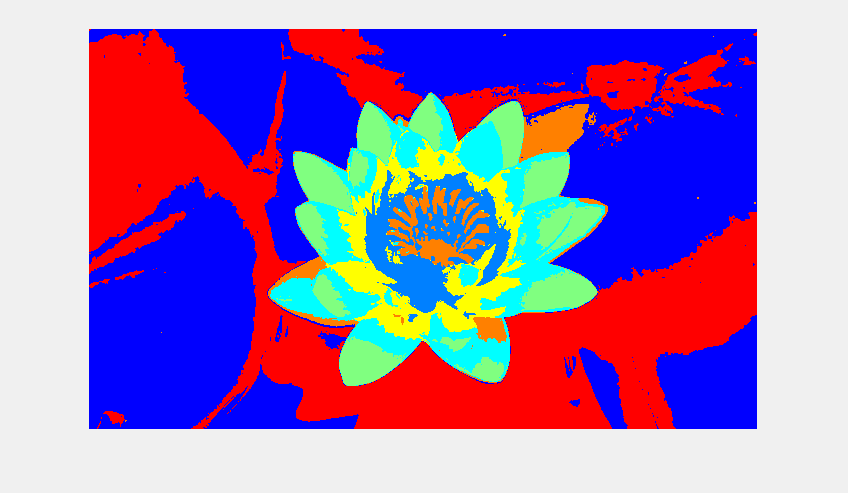

R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);
O = [R(:),G(:),B(:)];
[C Cen] = kmeans(double(O), n_colors);
[f c p] = size(I);
C = reshape(C,[f c]);
imshow(label2rgb(C));


MASK = double(zeros(f, c));
MASK(rect(2):rect(2)+rect(4), rect(1):rect(1)+rect(3)) = 1;
DINS = uint8(C.*MASK);
FORA = uint8(C.*not(MASK));

etiquetes_dins = uint8(zeros(n_colors));

dins = zeros(n_colors);
fora = zeros(n_colors);
for k = 1:n_colors
    dins(k) = numel(find(DINS==k));
    fora(k) = numel(find(FORA==k));
    etiquetes_dins(k) = dins(k) < fora(k);
end

Unable to perform assignment because the left and right sides have a different number of elements.


BIN = zeros(f, c);

for i = 1 : f
    for j = 1 : c
        BIN(i,j) = not(etiquetes_dins(C(i,j))); 
    end
end
imshow(BIN);
